# Sin Function Test

## Clear Workspace

close all; clearvars; clc;

## Vars

N = 500e3; % sets the length of buffer for preloading
sample_HZ = 1e6; % frequency HZ
A = 0.5; % amplitude p-pk V
f1 = 10e3; % lowest frequency component Hz
f2 = 30e3; % mid frequency component Hz
f3 = 50e3; % highest frequency component Hz
phase = pi; % phase of the system in degrees


## Wave Gen

t = 0:1/sample_HZ:((N/sample_HZ)-(1/sample_HZ))

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


outputSignal = [createSine(A, f1, f2, f3, 0, sample_HZ, "bipolar", N), createSine(A, f1, f2, f3, phase, sample_HZ, "bipolar", N)]'; % calls function to generate wave vector

## Plot Waves

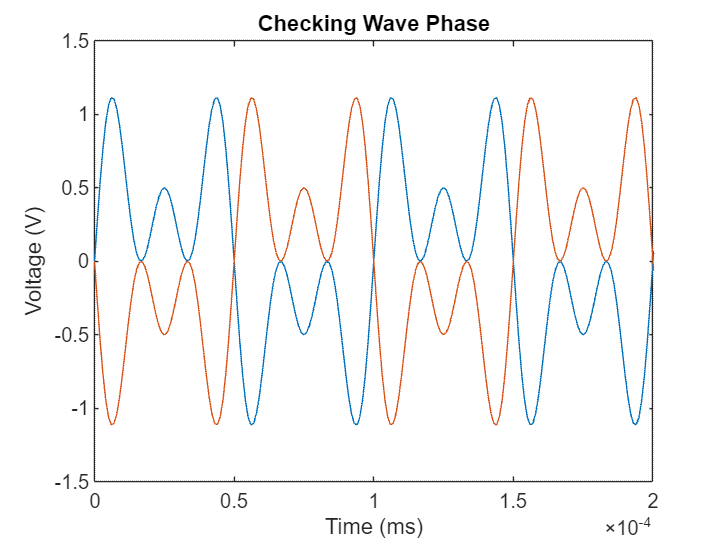

figure
plot(t, outputSignal)
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Checking Wave Phase')
xlim([0 0.2e-3])

## Sine Function

function sine = createSine(A, frq1, frq2, frq3, phase, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    periods = 1/eval(gcd(sym([frq1 frq2 frq3]))); % calculates the length of the period for a periodic
    t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period
        if type == "bipolar"
            y = A*sin(2*pi*frq1*t+phase) + A*sin(2*pi*frq2*t+phase) + A*sin(2*pi*frq3*t+phase); % calculates the signal along the time vector
        elseif type == "unipolar"
            y = A*sin(2*pi*frq1*t+phase) + A*sin(2*pi*frq2*t+phase) + A*sin(2*pi*frq3*t+phase) + A; % calculates the signal along the time vector
        end
    numCycles = ceil(bufferForPreLoad/(periods/timeStep)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end